digitDatasetPath = fullfile(matlabroot,'toolbox','nnet','nndemos', ...
'nndatasets','DigitDataset');

imds = imageDatastore(digitDatasetPath, ...
'IncludeSubfolders',true,'LabelSource','foldernames');

% Number of images taken for each class (from 0 to 1000)
numTrainFiles = 200;
[imdsTrain,imdsValidation] = splitEachLabel(imds,numTrainFiles,'randomize');

tr_in = readall(imdsTrain);
tr_tg = imdsTrain.Labels;

ts_in = readall(imdsValidation);
ts_tg = imdsValidation.Labels;

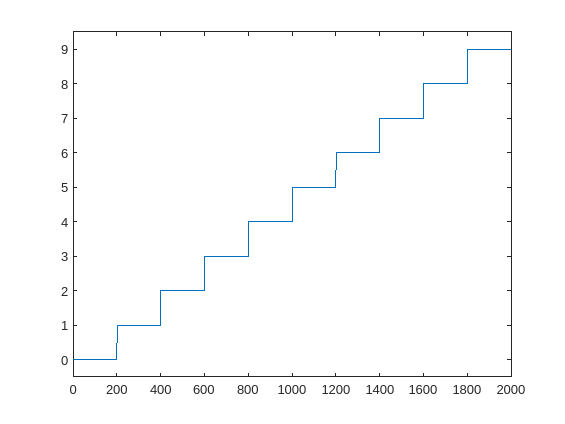

plot(tr_tg)

addpath src

Nz = 784;
f_in = @(x) inputAugmentation(x, Nz);
f_out = @(z, W_out) readout(z, W_out);
omega_b = 0.1;
T = 1;
%f = @(bias, hidden_weights, hidden) tanh(hidden_weights*hidden + bias);
f = @(bias, hidden_weights, hidden) (hidden_weights*hidden + bias);
phi = @rungeKutta;
eps = 0.01;
eigs = {[0 10], ones(1, Nz/2)};
ws = 0;
lambda_r = 0.1;
%Nl = 1;
seed = 1;

net = NeuralODE(f_in, f_out, omega_b, T, f, phi, eps, eigs, ws, lambda_r, seed);

% hidden = net.hiddenState(tr_in);
index_sample = 1;
input_sample = tr_in(index_sample);

% Reshape to sequence of images
hidden_sample = reshape(hidden_sample{:},[sqrt(Nh),sqrt(Nh),size(hidden_sample{:},2)]);

Error using reshape
Number of elements must not change. Use [] as one of the size inputs to automatically calculate the appropriate size for that dimension.


% Play video
implay(hidden_sample)

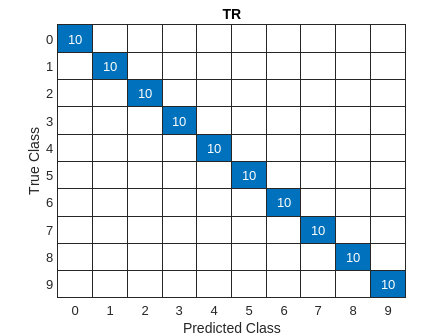

[net,pred_tr]=net.fit(tr_in,tr_tg);
figure
confusionchart(tr_tg, pred_tr);
title("TR")